# パラメータを更新

clear

%重力加速度
g = 9.8; %[m/s^2]

% 効率
eta = 0.7; % 走行抵抗やギアの損失をもろもろ考慮した効率

% 機構的なパラメータ
M = 2000e-3; % 重量[kg]
l1 = 160e-3; % 第1リンクの長さ[m]
l2 = 160e-3; % 第2リンクの長さ[m]

% モータのパラメータ
V_input = 24; % 印加電圧[V]
V_nominal = 24; %モータの公称電圧[V]
voltage_constant_times = V_input / V_nominal;

n_max = 4530 * voltage_constant_times; % 無負荷回転数[rpm]
omega_max = (n_max * 2 * pi) / 60; % 無負荷角速度[rad/s]
T_max = 85.3e-3 * voltage_constant_times; % 停動トルク[Nm]

n_const = 195 * voltage_constant_times; % 回転数定数[rpm/V]
omega_const = n_const * 2 * pi / 60; % 角速度定数[rad/V]
T_const = 49e-3 * voltage_constant_times; %トルク定数[Nm/A]


# モータの特性をプロット

#### 回転数-トルク特性

% sloop = -n_max / T_max; %傾きを計算
% fplot(@(x) sloop * x + n_max, [0 T_max]);
torque_motor = linspace(0, T_max);
n_motor = linspace(n_max, 0);
plot(torque_motor, n_motor);
xlabel("トルク [Nm]")
ylabel("回転数 [rpm]")

#### 出力特性

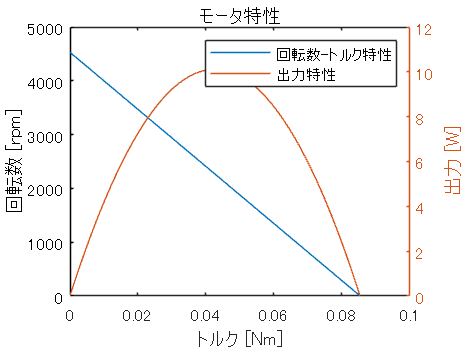

omega_motor = linspace(omega_max, 0);
P_motor = torque_motor .* omega_motor; %出力を計算

hold on
yyaxis right
plot(torque_motor, P_motor);
ylabel("出力 [W]")
legend("回転数-トルク特性", "出力特性")
title("モータ特性")

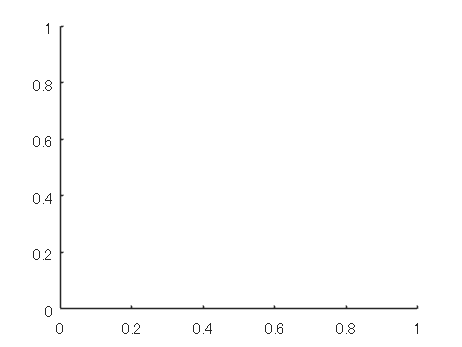

cla reset
hold off


P_motor = max(double(P_motor)) %モータの最大出力

P_motor = 10.1151

p_motor = (omega_max / 2) * (T_max / 2) % 厳密解

p_motor = 10.1162

# 自重を支えることができるトルクを計算

theta1 = deg2rad(180); %関節の角度
phi1 = pi - theta1;

F_M = -(1/4) * M * g;
T1 = l1 * F_M * cos(phi1)

T1 = -0.7840

# 脚に必要な出力を算出

任意の高さをジャンプできる出力を計算

% % タイヤに必要な角速度とトルク．走行抵抗などで余計にトルクが必要な場合を効率として考慮
% omega_tire_need = (max_velocity / r);
% torque_tire_need = (r * (m/2) * max_acceleration) / eta; % タイヤが2個ついているので1つのタイヤにかかる重量は半分
% 
% % タイヤに必要な出力（効率考慮済み）
% P_tire_need = omega_tire_need * torque_tire_need
% 

# 減速機なしの状態で駆動点と比較

%  % 角速度-トルク特性
% plot(torque_motor, omega_motor);
% 
% hold on
% % 出力
% P_n = torque_motor .* omega_motor; %出力を計算
% yyaxis right
% plot(torque_motor, P_n); % 出力特性
% ylabel("出力 [w]")
% 
% % 必要な出力の範囲
% above_idx = find(P_n >= P_tire_need); %P_tire_need以上の出力のインデックスを取得
% area(torque_motor(above_idx), P_n(above_idx), 'LineStyle', 'none', 'FaceColor', 'cyan', 'FaceAlpha', 0.2) %塗りつぶし
% yyaxis left
% 
% % 駆動点
% scatter(torque_tire_need, omega_tire_need);
% 
% hold off
% 
% xlabel("トルク [Nm]")
% ylabel("角速度 [ras/d]")
% legend("モータの角速度-トルク特性", "タイヤの駆動点", "出力", "タイヤに必要な出力の範囲")
% title("駆動点での動作が不可能なケース")
% 
% cla reset

# 減速比によって特性グラフと駆動点がどのように移動するか確認

% ratio_guess = 1; %適当な減速比を入力．大きくなると角速度：小，トルク：大
% plot(torque_motor / ratio_guess, omega_motor * ratio_guess); % 角速度-トルク特性
% hold on
% 
% % 出力
% P_n = (torque_motor / ratio_guess) .* (omega_motor * ratio_guess); %出力を計算
% yyaxis right
% plot((torque_motor / ratio_guess), P_n); % 出力特性
% ylabel("出力 [w]")
% 
% % 必要な出力の範囲
% above_idx = find(P_n >= P_tire_need); %P_tire_need以上の出力のインデックスを取得
% area((torque_motor(above_idx) / ratio_guess), P_n(above_idx), 'LineStyle', 'none', 'FaceColor', 'cyan', 'FaceAlpha', 0.2) %塗りつぶし
% 
% yyaxis left
% 
% scatter(torque_tire_need, omega_tire_need);
% 
% hold off
% 
% xlabel("トルク [Nm]")
% ylabel("角速度 [ras/d]")
% legend("モータの角速度-トルク特性", "タイヤの駆動点", "出力", "タイヤに必要な出力の範囲")
% title(['駆動点で動作が可能なケース 減速比：', num2str(ratio_guess)])
% 
% cla reset
% 

# 条件を満たす範囲のイメージ

青い線がオレンジの線より上にあれば要求を満たす．

% syms omega_m gamma T_m T_n omega_n tau %omega(tau) omega_a(tau)
% 
% omega = -(omega_m / T_m) * gamma^2 * tau + omega_m * gamma
% omega_a = -(omega_m / T_m) * gamma^2 * (tau - T_n) + omega_n
% 
% %代入
% ratio_guess = 0.1; %適当な減速比を入力．
% 
% omega = subs(omega, [gamma T_n omega_n T_m omega_m], [ratio_guess torque_tire_need omega_tire_need T_max omega_max])
% omega_a = subs(omega_a, [gamma T_n omega_n T_m omega_m], [ratio_guess torque_tire_need omega_tire_need T_max omega_max])
% 
% %減速比を介したタイヤの特性グラフ
% fplot(omega, [0 torque_tire_need*2])
% 
% hold on
% 
% %減速比（傾き）が同じで駆動点を通る線（要求を満たす限界ライン）
% fplot(omega_a, [0 torque_tire_need*2])
% 
% ylim([0 omega_tire_need*2])
% 
% scatter(torque_tire_need, omega_tire_need, 'red', 'filled')
% hold off
% 
% legend("\omega：減速比を介した特性", "\omega_a：同じ減速比で駆動点を通る線", "駆動点")

# 条件を満たす減速比の範囲を計算（1）

減速比なしのモータの出力から計算．wikiに書いてある方法．式の途中で減速比をいきなり考慮しちゃっている以外はwikiと同じだと思われ．

% syms P_n
% eqn1 = -(omega_m / T_m) * tau^2 + omega_m * tau == P_n % 出力の2次方程式の解がPnになる式
% 
% eqn1 = subs(eqn1, tau, T_n * gamma) %gammaについての式に変換
% 
% eqn1 = solve(eqn1, gamma) % gammaについて解く
% 
% eqn1_num = subs(eqn1, [omega_m T_m T_n omega_n P_n], [omega_max T_max torque_tire_need omega_tire_need P_tire_need]) %値を代入
% 
% g = double(eqn1_num) % 減速比
% 

# 条件を満たす減速比の範囲を計算（2）

駆動点より上にタイヤの角速度-トルク特性がくるような条件から計算．別解．

% eqn1 = omega_m * gamma == (omega_m/T_m) * gamma^2 * T_n + omega_n 
% 
% eqn1 = solve(eqn1, gamma) %減速比について解く（減速比：γ）
% 
% eqn1_num = subs(eqn1, [omega_m T_m T_n omega_n], [omega_max T_max torque_tire_need omega_tire_need]) % 値を代入
% 
% g = double(eqn1_num) % 減速比
% 

# プロットしてみる

#### 減速比が低いとき（速度重視）

% %減速比をかけた角速度-トルク曲線をプロット
% ratio_min = g(1);
% torque_motor_ratio_min = linspace(0, T_max * (1/ratio_min), 2000);
% omega_motor_ratio_min= linspace(omega_max * ratio_min, 0, 2000);
% 
% plot(torque_motor_ratio_min, omega_motor_ratio_min, 'Color', [0 0.4470 0.7410]); % 角速度-トルク特性
% xlabel("トルク [Nm]")
% ylabel("角速度 [ras/d]")
% 
% % 出力をプロット
% P_ratio_num_min = torque_motor_ratio_min .* omega_motor_ratio_min; %出力を計算
% yyaxis right
% hold on
% plot(torque_motor_ratio_min, P_ratio_num_min, 'LineStyle', ':', 'Color', 'blue'); % 出力特性
% ylabel("出力 [w]")
% 
% % 要求仕様を満たす出力の範囲
% above_idx_min = find(P_ratio_num_min >= P_tire_need); %P_tire_need以上の出力のインデックスを取得
% area(torque_motor_ratio_min(above_idx_min), P_ratio_num_min(above_idx_min), 'LineStyle', 'none', 'FaceColor', 'cyan', 'FaceAlpha', 0.2)
% 
% 
% % 加減速時の駆動点をプロット
% yyaxis left
% scatter(torque_tire_need, omega_tire_need, "green", 'filled'); %駆動点
% hold off
% 
% legend("タイヤの回転数-トルク特性", "タイヤの駆動点", "出力特性", "要求仕様を満たす出力の範囲")
% title(['速度重視　減速比：', num2str(g(1))])
% 
% cla reset

#### 減速比が高いとき（加速重視）

% %減速比をかけた角速度-トルク曲線をプロット
% 
% ratio_max = g(2);
% torque_motor_ratio_max = linspace(0, T_max * (1/ratio_max), 2000);
% omega_motor_ratio_max = linspace(omega_max * ratio_max, 0, 2000);
% 
% plot(torque_motor_ratio_max, omega_motor_ratio_max, 'Color', [0.8500 0.3250 0.0980]); % 角速度-トルク特性
% xlabel("トルク [Nm]")
% ylabel("角速度 [ras/d]")
% 
% % 出力をプロット
% P_ratio_num_max = torque_motor_ratio_max .* omega_motor_ratio_max; %出力を計算
% yyaxis right
% hold on
% plot(torque_motor_ratio_max, P_ratio_num_max, 'LineStyle', ':', 'Color', 'red'); % 出力特性
% ylabel("出力 [w]")
% 
% % 要求仕様を満たす出力の範囲
% above_idx_max = find(P_ratio_num_max >= P_tire_need); %P_tire_need以上の出力のインデックスを取得
% area(torque_motor_ratio_max(above_idx_max), P_ratio_num_max(above_idx_max), 'LineStyle', 'none', 'FaceColor', 'yellow', 'FaceAlpha', 0.2)
% 
% 
% % 加減速時の駆動点をプロット
% yyaxis left
% scatter(torque_tire_need, omega_tire_need, "green", 'filled'); %駆動点
% hold off
% 
% legend("タイヤの回転数-トルク特性", "タイヤの駆動点", "出力特性", "要求仕様を満たす出力の範囲")
% title(['加速度重視　減速比：', num2str(g(2))])
% 
% cla reset

#### 重ねて表示

% %モータ特性をプロット
% plot(torque_motor_ratio_min, omega_motor_ratio_min, torque_motor_ratio_max, omega_motor_ratio_max); % 角速度-トルク特性
% xlabel("トルク [Nm]")
% ylabel("角速度 [ras/d]")
% 
% hold on
% % 加減速時の駆動点をプロット
% scatter(torque_tire_need, omega_tire_need, "green", 'filled'); %駆動点
% 
% %　出力をプロット
% yyaxis right
% plot(torque_motor_ratio_min, P_ratio_num_min, 'LineStyle', ':', 'Color', 'blue'); % 出力特性
% plot(torque_motor_ratio_max, P_ratio_num_max, 'LineStyle', ':', 'Color', 'red'); % 出力特性
% 
% ylabel("出力 [w]")
% 
% area(torque_motor_ratio_min(above_idx_min), P_ratio_num_min(above_idx_min), 'LineStyle', 'none', 'EdgeColor', 'black', 'FaceColor', 'cyan', 'FaceAlpha', 0.2)
% area(torque_motor_ratio_max(above_idx_max), P_ratio_num_min(above_idx_max), 'LineStyle', 'none', 'EdgeColor', 'black', 'FaceColor', 'yellow', 'FaceAlpha', 0.2)
% 
% hold off
% 
% legend("最高速度重視のモータ特性", "最高加速重視のモータ特性")